# Punto 3.4.1

# Pitchfork  Bifurcation.

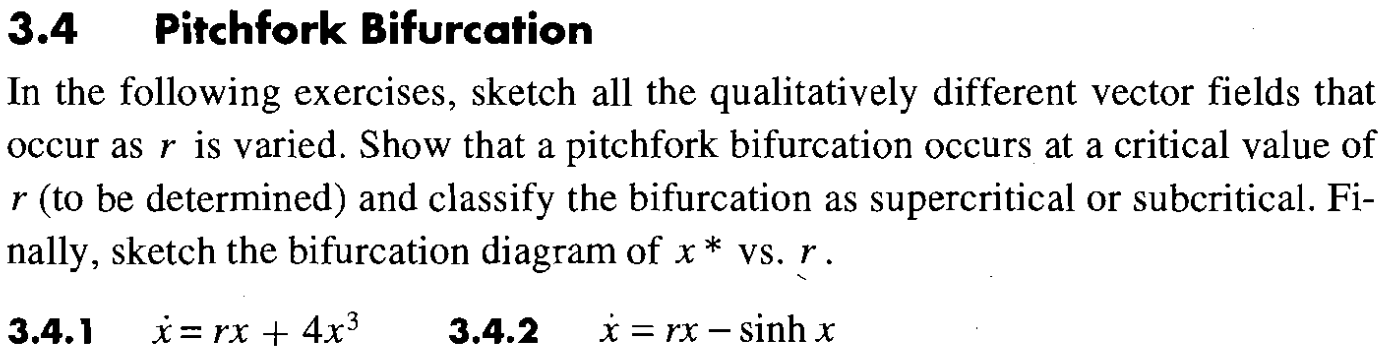

clc;clear;close all

## Bifurcación Saddle-Node

Para este tipo de bifurcación, se analiza el siguiente sistema:-


$$\dot{x} =r*x+{4x}^3$$


Donde $r$ es el parámetro de bifurcación

syms x r
Fsn = r*x+4*x^3

$$Fsn = 4\,x^{3}+r\,x$$

disp("Ejercicio 3.4.1");

Ejercicio 3.4.1


r_asignada=-8

r_asignada = -8

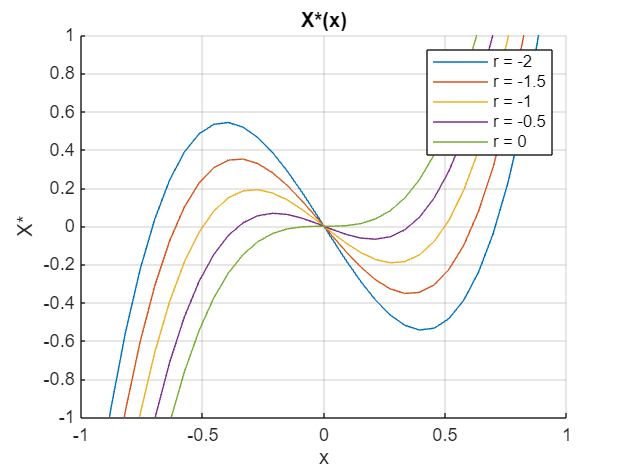

% GRAFICA X*(x):
r_desde = -2;
r_hasta = 0;
r_paso = 0.5; % Reducido el paso para una mejor visualización
r_grafica = r_desde:r_paso:r_hasta; % Vector de valores de r
x_desde = -3;
x_hasta = 3;
x_grafica = linspace(x_desde, x_hasta, 100);
figure; % Abre una nueva figura para la gráfica
hold on;
for i = 1:length(r_grafica)
    Fsn_grafica = real(subs(subs(Fsn, r, r_grafica(i)), x, x_grafica)); % Sustituye r y x por valores específicos y evalúa Fsn
    plot(x_grafica, Fsn_grafica); % Grafica Fsn con valores de r específicos
end
xlim([-1 1])
ylim([-1 1]) 
grid on
title("X*(x)");
xlabel("x")
ylabel("X*")
hold off;
legend(arrayfun(@(r) ['r = ' num2str(r)], r_grafica', 'UniformOutput', false)); % Crea la leyenda con los valores de r

Para analizar este sistema, se encuentra los PE, linealizando alrededor de estos puntos y se analiza la estabilidad de cada uno.

xss_sn = simplify(solve(Fsn==0,x),"Steps",100)

$$xss\_sn = \left(\begin{array}{c} 0\\ -\frac{\sqrt{-r}}{2}\\ \frac{\sqrt{-r}}{2} \end{array}\right)$$

En este caso, tenemos 3 PE. Por lo que se linealiza en estos puntos

A = jacobian(Fsn,x)

$$A = 12\,x^{2}+r$$


A_a = subs(A,x,xss_sn(1)) % Para el punto de equilibrio 1

$$A\_a = r$$

A_aevaluado=double(subs(A_a,r,r_asignada))

A_aevaluado = -8

A_b = subs(A,x,xss_sn(2)) % Para el punto de equilibrio 2 

$$A\_b = -2\,r$$

A_bevaluado=double(subs(A_b,r,r_asignada))

A_bevaluado = 16

A_c = subs(A,x,xss_sn(3))

$$A\_c = -2\,r$$

A_cevaluado=double(subs(A_c,r,r_asignada))

A_cevaluado = 16

En este caso, para los tres PE se hace el siguiente análisis:

- Para $x_a =0$

Se tiene que el jacobiano $A=r$, para este caso $r<0\;$, con el fin de tener un valor estable para este polo. 

- Para $x_b =-\frac{\sqrt{-r}}{2}$

Se tiene que el jacobiano $A=$$-2r$, nuevamente, se debe cumplir que $r<0\;$, para que los valores de $x_b$ sean reales, aunque esto haga que el polo sea inestable.

- Para $x_c =\frac{\sqrt{-r}}{2}$

Se tiene que el jacobiano $A=$$-2r$, nuevamente, se debe cumplir que $r<0\;$, para que los valores de $x_b$ sean reales, aunque esto haga que el polo sea inestable.

Si hacemos que $r=-8$ 

xss_sn_num = double(subs(xss_sn,r,r_asignada))

xss_sn_num =          0
   -1.4142
    1.4142


## Simulación de la Bifurcación Saddle - Node

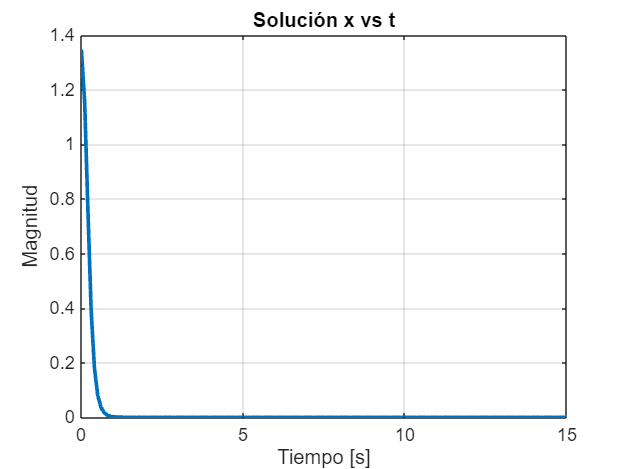

Tsim = 15;              % Tiempo de simulación
Ts = 0.1;               % Periodo de muestreo
x0 = 1.4;        % Condiciones iniciales
Ns = round(Tsim/Ts);    % Iteraciones
r_sim = linspace(-4,4,Ns);
t_sim = linspace(0,Ns*Ts,Ns);

% Solución ED
for i = 1:Ns
    % Simulación de la ED

    [t1,xd] = ode45(@(t,x) saddlenode(t,x,r_asignada), [0 Ts], x0);
    x0 = xd(end,:)';

    % Análisis de Bifurcación

    fr(:,i) = double(subs(xss_sn,r,r_sim(i)));

    if imag(fr(:,i)) ~= 0
        fr(:,i) = NaN;      % Elimina los valores imaginarios cuando evalúa los posibles valores de r en los PE
    end
 
    % Guardar valores
    x_sim(i) = x0;
end

% Gráficas

figure("Name","Solución del sistema y diagrama de bifurcación")

plot(t_sim,x_sim,LineWidth=2)
xlabel("Tiempo [s]")
ylabel("Magnitud")
title("Solución x vs t")
grid on

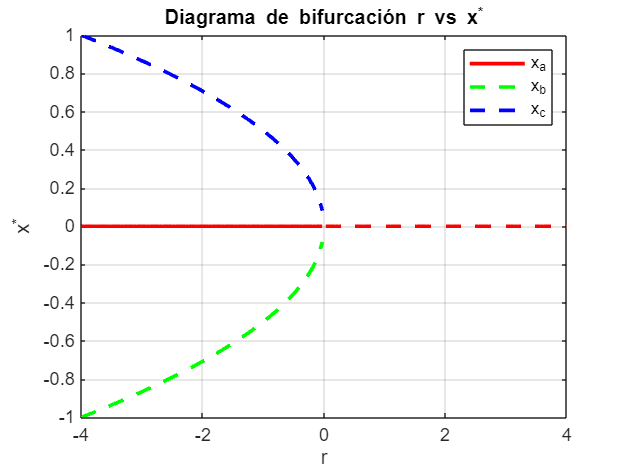


plot(r_sim(r_sim <= 0), real(fr(1, r_sim <= 0)), 'LineWidth', 2, 'Color', 'r');
hold on
plot(r_sim(r_sim <= 0), real(fr(2, r_sim <= 0)), 'LineWidth', 2, 'Color', 'g', 'LineStyle', '--');
plot(r_sim(r_sim <= 0), real(fr(3, r_sim <= 0)), 'LineWidth', 2, 'Color', 'b', 'LineStyle','--');
plot(r_sim(r_sim >= 0), real(fr(1, r_sim >= 0)), 'LineWidth', 2, 'Color', 'r','LineStyle', '--');
hold off
legend(["x_a" "x_b" "x_c"])
title("Diagrama de bifurcación r vs x^*")
xlabel("r")
ylabel("x^*")
grid on

#### Bifurcación Saddle - Node

function dxdt = saddlenode(t,x,r)
    dxdt = r*x+4*(x^3);
end